導入檔案要求:

第一行:matlab數據x(角度)

第二行:matlab數據y(矩)

第一行:solidworks數據x(角度)

第二行:solidworks數據y(矩)

clear;
filePath="D:\SynologyDrive\ISEF\SEPT-Paper\MATLAB\matData\SolidworksMatlabComparison.mat"
load (filePath);    

isNZ=(~SolidworksMatlabComparison(4,:)==0);
x=SolidworksMatlabComparison(3,isNZ);
y=SolidworksMatlabComparison(4,isNZ);

plot(SolidworksMatlabComparison(1,:), SolidworksMatlabComparison(2,:),"DisplayName","Matlab result"); hold on;

xq = -20:0.2:60;
yq = interp1(x,y,xq,"linear"); %interpolation of Matlab data for calculating RMSE

plot(xq,yq,"DisplayName","(linear)interpolated Soliwork results"); hold off;
xlabel("\theta");
ylabel("Momont at O'4");
title("Comparison of moment at O'4 between Matlab calculation and Solidworks simulation with RMSE");
legend;

rmse = RMSE(yq, SolidworksMatlabComparison(2,:));

rmse = 8.7051

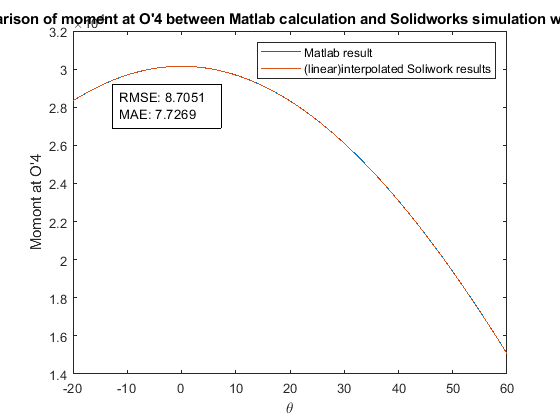

mae = MAE(yq, SolidworksMatlabComparison(2,:));

 %***textbox***%
dim = [.2 .5 .3 .3];
str = "RMSE: " +rmse;
str = compose(str);
str2 = "MAE: " +mae;
str2 = compose(str2);
annotation('textbox',dim,'String',str + newline + str2,'FitBoxToText','on');

%*************%

function rmse = RMSE(V1,V2)
    rmse = sqrt(mean((V1-V2).^2))
end
function mae = MAE(V1,V2)
    mae = mean(abs(V1-V2));
end